wind_data = readtable("BNKJUL001_Thesis_Wind500kGenHomer.csv")

wind_data = 8760×2 table
             Time             Wind_Out
    ______________________    ________

    01/01/2007 12:00:00 AM     61.478 
    01/01/2007 01:00:00 AM     36.949 
    01/01/2007 02:00:00 AM     42.087 
    01/01/2007 03:00:00 AM     84.377 
    01/01/2007 04:00:00 AM     167.44 
    01/01/2007 05:00:00 AM     239.07 
    01/01/2007 06:00:00 AM     436.85 
    01/01/2007 07:00:00 AM     497.53 
    01/01/2007 08:00:00 AM     499.37 
    01/01/2007 09:00:00 AM        500 
    01/01/2007 10:00:00 AM     464.86 
    01/01/2007 11:00:00 AM     496.45 
    01/01/2007 12:00:00 PM     423.15 
    01/01/2007 01:00:00 PM     338.31 
    01/01/2007 02:00:00 PM        341 
    01/01/2007 03:00:00 PM     334.64 


pv_data = readtable("BNKJUL001_Thesis_solarGen500kWHomer.csv")

pv_data = 8760×2 table
             Time             PV_Out
    ______________________    ______

    01/01/2007 12:00:00 AM         0
    01/01/2007 01:00:00 AM         0
    01/01/2007 02:00:00 AM         0
    01/01/2007 03:00:00 AM         0
    01/01/2007 04:00:00 AM         0
    01/01/2007 05:00:00 AM         0
    01/01/2007 06:00:00 AM    26.393
    01/01/2007 07:00:00 AM    69.626
    01/01/2007 08:00:00 AM    115.05
    01/01/2007 09:00:00 AM    188.93
    01/01/2007 10:00:00 AM    74.453
    01/01/2007 11:00:00 AM    65.394
    01/01/2007 12:00:00 PM    221.67
    01/01/2007 01:00:00 PM    202.77
    01/01/2007 02:00:00 PM    106.29
    01/01/2007 03:00:00 PM    66.523


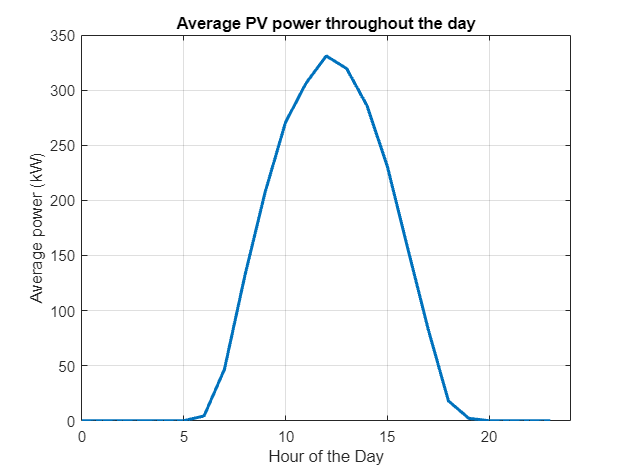


hours = hour(pv_data.Time);

% For each unique hour, calculate the average value
uniqueHours = unique(hours);
averageValues = arrayfun(@(h) mean(pv_data.PV_Out(hours == h)), uniqueHours);

% Plotting the results
plot(uniqueHours, averageValues ,'LineWidth', 2);
xlabel('Hour of the Day');
ylabel('Average power (kW)');
title('Average PV power throughout the day');
ylim([0,350])
xlim([0,24])
grid on;

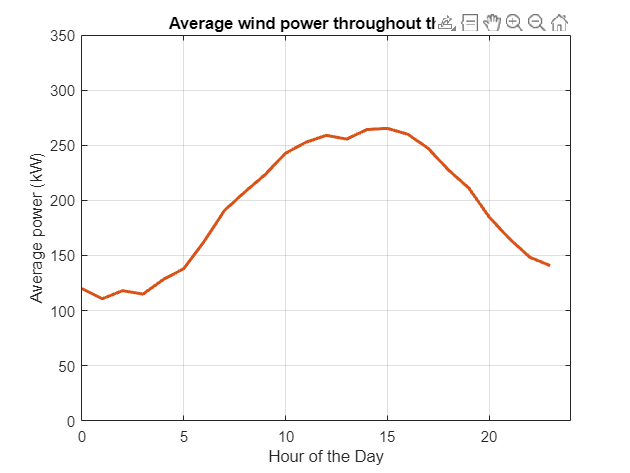


hours = hour(wind_data.Time);

% For each unique hour, calculate the average value
uniqueHours = unique(hours);
averageValues = arrayfun(@(h) mean(wind_data.Wind_Out(hours == h)), uniqueHours);

% Plotting the results
plot(uniqueHours, averageValues,'LineWidth', 2, 'Color', [0.8500, 0.3250, 0.0980]);
xlabel('Hour of the Day');
ylabel('Average power (kW)');
title('Average wind power throughout the day');
ylim([0,350])
xlim([0,24])
grid on;